clear
% Step 1
% Mean Gaussian = 0
% Variance Gaussian = sigma^2

mu = 0;
sigma = sqrt(2);
M = 10000;

data = normrnd(mu, sigma, 1, M);

disp('Random Gaussian Distribution:');

Random Gaussian Distribution:


disp(data);

  Columns 1 through 3,276

   -0.3421    0.5303    0.8670   -0.5429   -2.1392    1.5268   -0.4519   -0.5915    1.8315    1.6310    1.7583    2.1687    1.6889   -1.2539    2.4668    1.3722   -2.8053    1.0282   -0.1879   -2.3265    1.0546   -0.9112   -0.2089   -1.7827   -0.1741   -2.0884   -0.1629   -1.9116    0.2125   -0.6079   -1.5518    0.3855    1.8159    0.8149    0.9384    0.5106   -2.8923    1.9629   -1.3286   -1.3969   -1.0619   -1.5329    1.1480    0.0324   -2.0509    4.5351   -2.2001    0.0755    3.8492    1.8287    2.2207    0.7720    1.2741    1.8327   -0.2205   -0.8148   -2.6131   -0.5816   -0.0653    2.0603   -1.0540    0.3684    1.3740   -0.0568   -0.2498    0.1996    0.9025   -0.9606    0.3173    0.2182   -2.6836   -2.5267    1.1749    0.4708    1.7387    1.6077   -0.3487    1.7252   -0.6143   -0.2080    1.8282    1.1315    1.3148   -1.1143    0.7181    0.4551   -0.8797    0.7919    1.4358   -3.0557    0.4571   -0.4893    0.4750   -0.6294    0.0852   -1.8920    0.8415   

% Step 2

mu_s = mean(data);      % Sample Mean of Data
sigma_s = std(data);    % Sample Standard Deviation of Data

disp(['Sample Mean: ', num2str(mu_s)]);

Sample Mean: -0.0056963


disp(['Sample Standard Deviation: ', num2str(sigma_s)]);

Sample Standard Deviation: 1.4263


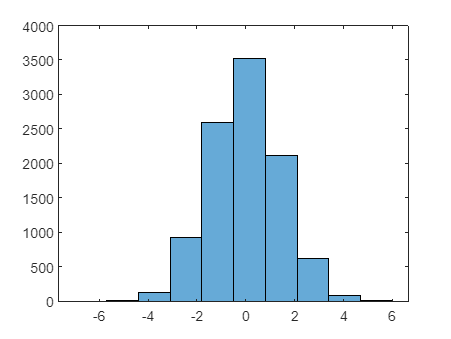

% Step 3

K = 10;
h = histogram(data, K);

mj = h.Values;                                  % # Samples In Each Bin
Cj = h.BinEdges(1:end-1) + diff(h.BinEdges)/2;  % Centers Of Each Bin (From Documentation)

disp('Bin Samples (mj):');

Bin Samples (mj):


disp(mj);

           6          72         637        2165        3489        2596         895         130           9           1



disp('Bin Centers (Cj):');

Bin Centers (Cj):


disp(Cj);

   -5.3500   -4.0500   -2.7500   -1.4500   -0.1500    1.1500    2.4500    3.7500    5.0500    6.3500



% Step 4

delta = (Cj(end) - Cj(1)) / (K - 1);    % (End Bin - Start Bin) / # Gaps

disp(['Bin Length Delta: ', num2str(delta)]);

Bin Length Delta: 1.3


% Step 5

simulated_pdf = mj / (M * delta);   % Directly From Lab Procedure

disp('Simulated pdf at Bin Centers:');

Simulated pdf at Bin Centers:


disp(simulated_pdf);

    0.0005    0.0055    0.0490    0.1665    0.2684    0.1997    0.0688    0.0100    0.0007    0.0001



% Step 6

numerator = -((Cj - mu_s).^2);          % Numerator
denominator = 2 * sigma_s^2;            % Denominator
scalar = 1 / (sigma_s * sqrt(2*pi));    % Scalar / Front Value?

theoretical_pdf = scalar * exp(numerator / denominator);

disp('Theoretical pdf at Bin Centers:');

Theoretical pdf at Bin Centers:


disp(simulated_pdf);

    0.0005    0.0055    0.0490    0.1665    0.2684    0.1997    0.0688    0.0100    0.0007    0.0001



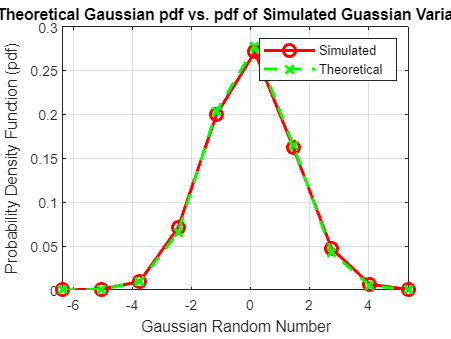

% Step 7

figure;
plot(Cj, simulated_pdf, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

plot(Cj, theoretical_pdf, 'g-x', 'LineStyle', '--', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Gaussian Random Number');
ylabel('Probability Density Function (pdf)');
title('Theoretical Gaussian pdf vs. pdf of Simulated Guassian Variates');
legend('Simulated', 'Theoretical');

grid on;
hold off;